# Bulk iHUMAN Differential Flux Analysis

**Author:** Scott Campit

## Summary

This script computes bulk differentially sensitive reactions resulting from reaction knockouts in the RECON1 metabolic model.

clear all;

## 1. Load data

We'll load the RECON1 data obtained from three independent studies:

- GSE17518 (Keshamouni transcriptomics)

- GSE17708 (Thannickal transcriptomics)

- Garcia proteomics data

### A. GSE17518

#### i. Load data

First we'll load all of the data as a single dataframe.

foldchange_labels = ["1/0hrs", "2/0hrs", "4/0hrs", "5min/0hrs", ...
                     "8/0hrs", "16/0hrs", "24/0hrs", "72/0hrs"];
datapath = dir(fullfile("D:/Analysis/EMT/gse17518/ihuman/", "*.mat"));
for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    GSE17518_flux(:, i) = cobra_cell.flux;
    id(i) = cobra_cell.id;
end

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

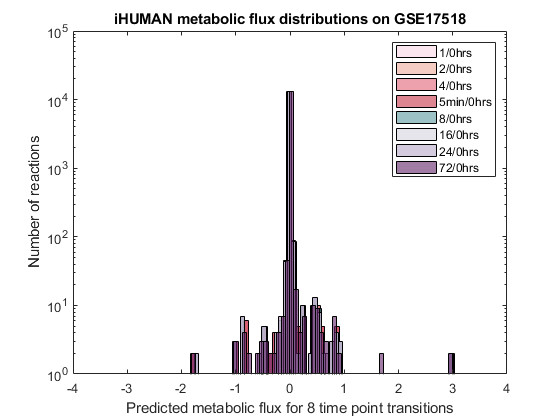

figure;
h1 = histogram(GSE17518_flux(:, 1), 100);
hold on;
h2 = histogram(GSE17518_flux(:, 2), 100);
hold on;
h3 = histogram(GSE17518_flux(:, 3), 100);
hold on;
h4 = histogram(GSE17518_flux(:, 4), 100);
hold on;
h5 = histogram(GSE17518_flux(:, 5), 100);
hold on;
h6 = histogram(GSE17518_flux(:, 6), 100);
hold on;
h7 = histogram(GSE17518_flux(:, 7), 100);
hold on;
h8 = histogram(GSE17518_flux(:, 8), 100);

set(h1, 'facecolor', "#f9d5e5");
set(h2, 'facecolor', "#eeac99");
set(h3, 'facecolor', "#e06377");
set(h4, 'facecolor', "#c83349");
set(h5, 'facecolor', "#5b9aa0");
set(h6, 'facecolor', "#d6d4e0");
set(h7, 'facecolor', "#b8a9c9");
set(h8, 'facecolor', "#622569");

legend(foldchange_labels);
set(gca, 'YScale', 'log')
title("iHUMAN metabolic flux distributions on GSE17518");
xlabel("Predicted metabolic flux for 8 time point transitions");
ylabel("Number of reactions");
xlim([-4, 4]);

### B. GSE17708

#### i. Load data

First we'll load all of the data as a single dataframe.

foldchange_labels = ["1/0hrs", "2/0hrs", "4/0hrs", "5min/0hrs", ...
                     "8/0hrs", "16/0hrs", "24/0hrs", "72/0hrs"];
datapath = dir(fullfile("D:/Analysis/EMT/gse17708/ihuman/", "*.mat"));
for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    GSE17708_flux(:, i) = cobra_cell.flux;
    id(i) = cobra_cell.id;
end

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

figure;
h1 = histogram(GSE17518_flux(:, 1), 100);
hold on;
h2 = histogram(GSE17518_flux(:, 2), 100);
hold on;
h3 = histogram(GSE17518_flux(:, 3), 100);
hold on;
h4 = histogram(GSE17518_flux(:, 4), 100);
hold on;
h5 = histogram(GSE17518_flux(:, 5), 100);
hold on;
h6 = histogram(GSE17518_flux(:, 6), 100);
hold on;
h7 = histogram(GSE17518_flux(:, 7), 100);
hold on;
h8 = histogram(GSE17518_flux(:, 8), 100);

set(h1, 'facecolor', "#f9d5e5");
set(h2, 'facecolor', "#eeac99");
set(h3, 'facecolor', "#e06377");
set(h4, 'facecolor', "#c83349");
set(h5, 'facecolor', "#5b9aa0");
set(h6, 'facecolor', "#d6d4e0");
set(h7, 'facecolor', "#b8a9c9");
set(h8, 'facecolor', "#622569");

legend(foldchange_labels);
set(gca, 'YScale', 'log')
title("iHUMAN metabolic flux distributions on GSE17518");
xlabel("Predicted metabolic flux for 8 time point transitions");
ylabel("Number of reactions");
xlim([-4, 4]);

### C. Garcia proteomics

#### i. Load data

First we'll load all of the data as a single dataframe.

foldchange_labels = ["1/0hrs", "2/0hrs", "4/0hrs", "5min/0hrs", ...
                     "8/0hrs", "16/0hrs", "24/0hrs", "72/0hrs"];
datapath = dir(fullfile("D:/Analysis/EMT/gse17518/ihuman/", "*.mat"));
for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    GSE17518_flux(:, i) = cobra_cell.flux;
    id(i) = cobra_cell.id;
end

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

figure;
h1 = histogram(GSE17518_flux(:, 1), 100);
hold on;
h2 = histogram(GSE17518_flux(:, 2), 100);
hold on;
h3 = histogram(GSE17518_flux(:, 3), 100);
hold on;
h4 = histogram(GSE17518_flux(:, 4), 100);
hold on;
h5 = histogram(GSE17518_flux(:, 5), 100);
hold on;
h6 = histogram(GSE17518_flux(:, 6), 100);
hold on;
h7 = histogram(GSE17518_flux(:, 7), 100);
hold on;
h8 = histogram(GSE17518_flux(:, 8), 100);

set(h1, 'facecolor', "#f9d5e5");
set(h2, 'facecolor', "#eeac99");
set(h3, 'facecolor', "#e06377");
set(h4, 'facecolor', "#c83349");
set(h5, 'facecolor', "#5b9aa0");
set(h6, 'facecolor', "#d6d4e0");
set(h7, 'facecolor', "#b8a9c9");
set(h8, 'facecolor', "#622569");

legend(foldchange_labels);
set(gca, 'YScale', 'log')
title("iHUMAN metabolic flux distributions on GSE17518");
xlabel("Predicted metabolic flux for 8 time point transitions");
ylabel("Number of reactions");
xlim([-4, 4]);

## 2. Compute global mean and standard deviation for metabolic fluxes

## 3. Compute p-values for metabolic fluxes